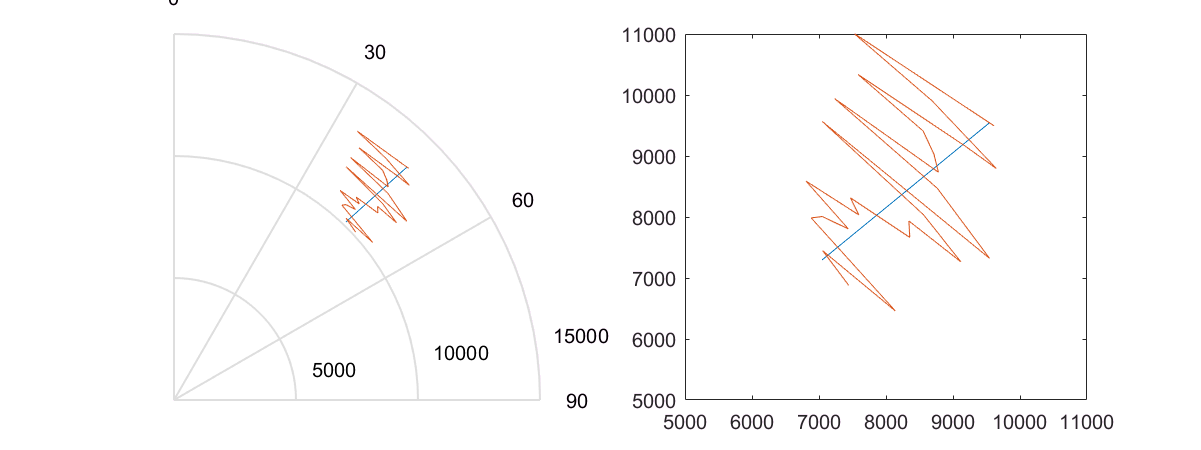

clc; clear; close all; 
addpath('functions/');

n = 26;

X = zeros(1,n);
Y = zeros(1,n);

x0 = 13500/(2)^(0.5);
y0=x0;
X(1) = x0;
Y(1) = y0;

V = [-50; -45];
t = 2;

sigmaB = 0.09;
sigmaD = 30;
BNoise = normrnd(0,sigmaB,1,n);
DNoise = normrnd(0,sigmaD,1,n);

for i=2:n
    X(i) = X(i-1) + V(1)*t; 
    Y(i) = Y(i-1) + V(2)*t; 
end

D = sqrt(X.^2 + Y.^2);  
B = atan( X ./ Y );
Dm = D + DNoise;
Bm = B + BNoise;





x = Dm .* sin(Bm);
y = Dm .* cos(Bm);

Z = [x; y];

figure ('position', [0, 0, 800, 300]); hold on;
subplot(1,2,1);
polar(B,D);hold on;
polar(Bm,Dm);
axis([0 inf 0 inf]);
view([90 -90]);


subplot(1,2,2);
plot(X,Y); hold on
plot(Z(1,:), Z(2,:));
axis([5000 11000 5000 11000])